%%%%%%SELECT OPTIONS:
problem_num = 2;
diff_opt = "forward"; %{forward, backward, centered}
partition_opt = "full"; %{full, partition}

%%%%%%SET UP NEURAL NETWORK
occurences = 1000;

%(1) Set up initial conditions and solve ODE:
function [C, t, h, arraySize, num_outputs] = probsetup(problem_num, occurences)
    if problem_num == 1
        %Problem #5: Dataset
        c0 = [10.0; 5.0; 0.0];
        tspan = linspace(0, 1, occurences); 
        h = 1/occurences;
        arraySize = [12 4];
        num_outputs = 3;
        
        k = [4.0; 2.0; 40.0; 20.0];
        dCdt = @(t, C)[
            -k(1)*C(1) + k(2)*C(2)
             k(1)*C(2) - (k(2) + k(3))*C(2) + k(4)*C(3) %TODO:DOUBLE CHECK k(1)C(2)
            -k(4)*C(3) + k(3)*C(2)
        ];

    elseif problem_num == 2
        c0 = [4.0; 1.0; 0.5; 0.0]; %initial condition
        tspan = linspace(0, 2, occurences); %constant time step
        h = 2/occurences;
        arraySize = [24 12];
        num_outputs = 4;
        
        k1 = 5.7; k2 = 6.1; 
        dCdt = @(t, C) [ %setup ODE
            -k1 * C(1) * t
             k2 * C(1) * t - k2 * C(2) * t
             k2 * C(2) * t
             k1 * C(1) * t + k2 * C(2) * t
        ];  
    end %if 
    options = odeset('MaxOrder', 5, 'BDF', 'on'); %BDF LIMITER
    [t, C] = ode15s(dCdt, tspan, c0, options); %solve ODE
end %function 

%(2) Calculate dX/dt
function [Xout, dXdt, dt] = diffmethod(Xin, t, h, diff_opt)
    if diff_opt == "forward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h; 
        Xout = [Xin(1:end-1,:) t(1:end-1)];         %Edited forward pass only.
        %Xout = Xin(1:end-1, :);
        dt = t(2:end) - t(1:end-1);
    end %if 
end %function

[C, t, h, arraySize, num_outputs] = probsetup(problem_num, occurences);
[X, Y, dt] = diffmethod(C, t, h, diff_opt);

**2ND ORDER ODE**

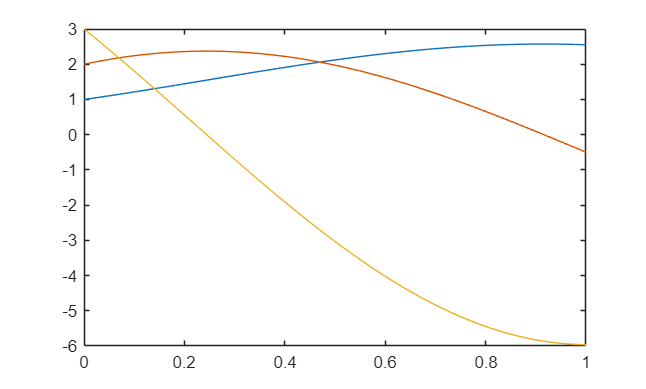

%%%%%%SELECT OPTIONS:
problem_num = 3;
diff_opt = "forward"; %{forward, backward, centered}
partition_opt = "full"; %{full, partition}

%%%%%%SET UP NEURAL NETWORK
occurences = 1000;

%(1) Set up initial conditions and solve ODE:
function [C, t, h, arraySize, num_outputs] = probsetup2(problem_num, occurences)
    if problem_num == 1 %dataset50
        % y" + a*y' + b*y = 0 can be converted to a 1st order ode by:
        % y1 = y
        % y2 = y1'
        % y2' = -a*y2 -b*y1

        c0 = [1.0; 0.0];
        tspan = linspace(0, 1, occurences); 
        h = 1/occurences;
        arraySize = [48 24 12 4];
        num_outputs = 2;
        
        k = [0.5; 4.0];
        dCdt = @(t, C)[
            C(2);                       %y1' = y2
            -k(1)*C(2) - k(2)*C(1);     %y2' = -a*y2 - b*y1
        ];
    elseif problem_num == 2 %dataset51
        %y1" = -k1C1 + k2C2
        %y2" = k1C1 - (k2+k3)C2 + k4C3
        %y3" = -k4C3 + k3C2
        %can be converted to 1st order ode by:
        %C[1:3] = Positions C[1:3]     => C" = a*C' 
        %C[4:6] = Velocities C'[1:3]   => C' = C 

        c0 = [1; 2; 3; 0.1; 0.2; 0.3];
        tspan = linspace(0, 1, occurences); 
        h = 1/occurences;
        arraySize = [48 24 12 4];
        num_outputs = 6;

        k = [4.0; 2.0; 40.0; 20.0];
        dCdt = @(t, C)[
             C(4);
             C(5);
             C(6);

            -k(1)*C(1) + k(2)*C(2)
             k(1)*C(1) - (k(2) + k(3))*C(2) + k(4)*C(3)
            -k(4)*C(3) + k(3)*C(2)
        ];
    elseif problem_num == 3 %dataset52
        %y"' + a y" + b y' + cy = 0  can be converted to 1st order:
        %y1' = y2
        %y2' = y3 
        %y3' = -ay3 - by2 - cy1

        c0 = [1; 2; 3];
        tspan = linspace(0, 1, occurences); 
        h = 1/occurences;
        arraySize = [48 24 12 4];
        num_outputs = 3;
        
        k = [0.5; 4.0; 2.0];
        dCdt = @(t, C)[
            C(2);                       %y1' = y2
            C(3);                       %y2' = y3
            -k(1)*C(3) - k(2)*C(2) - k(3)*C(1);     %y3' = -a*y3 - by2 - cy1
        ];
    end %if 
    % options = odeset('MaxOrder', 5, 'BDF', 'on'); %BDF LIMITER
    [t, C] = ode45(dCdt, tspan, c0); %solve ODE
end %function 

%(2) Calculate dX/dt
function [Xout, dXdt, dt] = diffmethod2(Xin, t, h, diff_opt)
    if diff_opt == "forward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h;   %Ytrain
        Xout = [Xin(1:end-1,:) t(1:end-1)];         %Xtrain 
        dt = t(2:end) - t(1:end-1);
    end %if 
end %function

[C, t, h, arraySize, num_outputs] = probsetup2(problem_num, occurences);
[X, Y, dt] = diffmethod2(C, t, h, diff_opt);

%%PHYSICS INFORMED: REMOVE Y1' = Y2:
% Y = Y(:, 2);

% figure;
% plot(t, C(:,1), 'b-', t, C(:, 2), 'r--');
% legend('Position (y1)', 'Velocity (y2)');

figure;
plot(t, C);

**REGULAR RELU**

%Regular ReLU
numFeatures = size(X, 2);
numOutputs = size(Y, 2);

layers = [
    featureInputLayer(numFeatures, 'Normalization','zscore','Name','input')

    fullyConnectedLayer(48, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(24, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(12, 'Name', 'fc3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(4, 'Name', 'fc4')
    reluLayer('Name', 'relu4')
    fullyConnectedLayer(numOutputs, 'Name', 'output')
]

layers =   10×1 Layer array with layers:

     1   'input'    Feature Input     4 features with 'zscore' normalization
     2   'fc1'      Fully Connected   48 fully connected layer
     3   'relu1'    ReLU              ReLU
     4   'fc2'      Fully Connected   24 fully connected layer
     5   'relu2'    ReLU              ReLU
     6   'fc3'      Fully Connected   12 fully connected layer
     7   'relu3'    ReLU              ReLU
     8   'fc4'      Fully Connected   4 fully connected layer
     9   'relu4'    ReLU              ReLU
    10   'output'   Fully Connected   3 fully connected layer

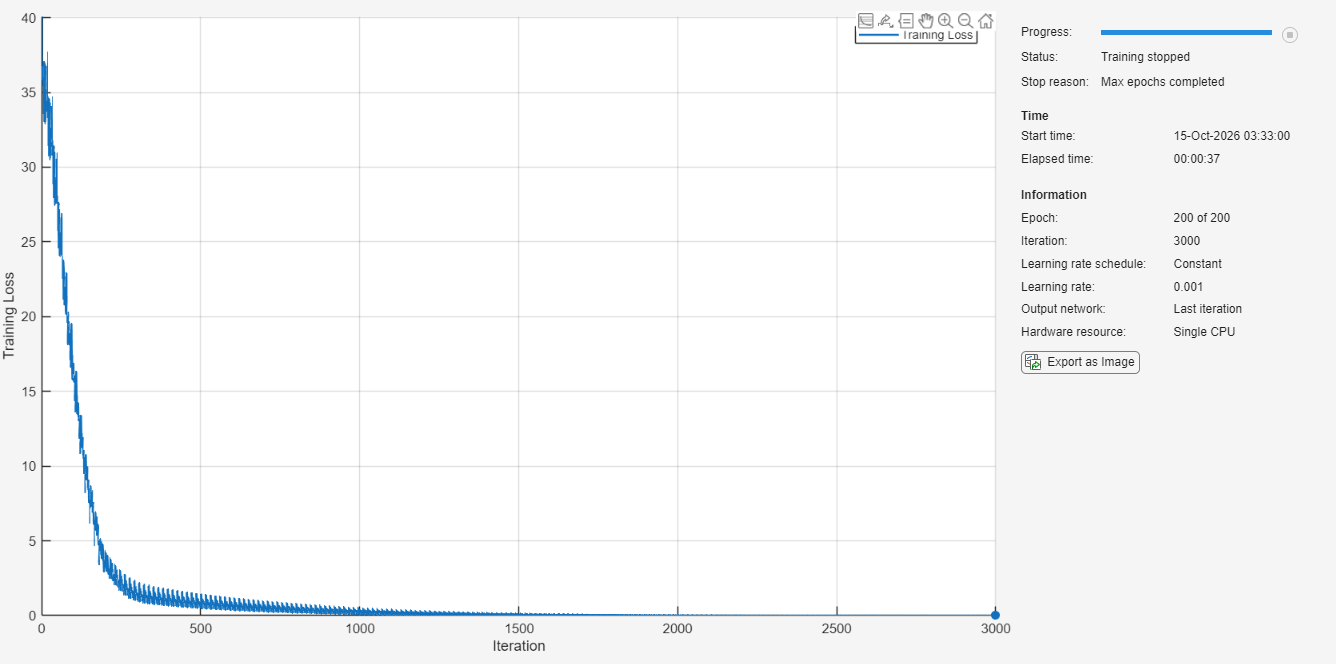


options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 1e-3, ...
    'Plots', 'training-progress', ...
    'Verbose', false);

trainedNet = trainnet(X, Y, layers, "mse",options);

**LEAKY RELU**

%Leaky ReLU
numFeatures = size(X, 2);
numOutputs = size(Y, 2);
alphaParameter = 0.01;

layers = [
    featureInputLayer(numFeatures, 'Normalization','zscore','Name','input')
    
    fullyConnectedLayer(12, 'Name', 'fc1')
    leakyReluLayer(alphaParameter, 'Name', 'relu1')
    fullyConnectedLayer(4, 'Name', 'fc2')
    leakyReluLayer(alphaParameter, 'Name', 'relu2')
    fullyConnectedLayer(numOutputs, 'Name', 'output')
]

layers =   6×1 Layer array with layers:

     1   'input'    Feature Input     4 features with 'zscore' normalization
     2   'fc1'      Fully Connected   12 fully connected layer
     3   'relu1'    Leaky ReLU        Leaky ReLU with scale 0.01
     4   'fc2'      Fully Connected   4 fully connected layer
     5   'relu2'    Leaky ReLU        Leaky ReLU with scale 0.01
     6   'output'   Fully Connected   3 fully connected layer

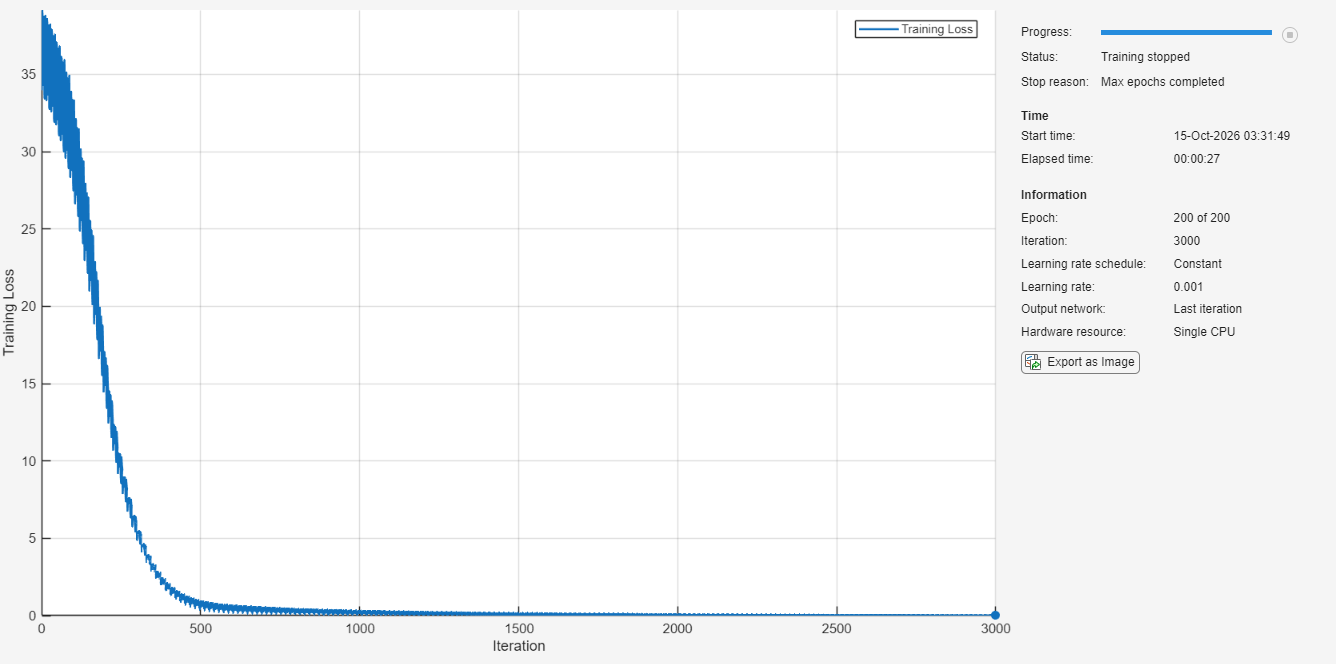

trainedNet =   dlnetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [6×3 table]
          State: [0×3 table]
     InputNames: {'input'}
    OutputNames: {'output'}
    Initialized: 1

  View summary with summary.



options = trainingOptions( ...
    'adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 1e-3, ...
    'Plots', 'training-progress', ...
    'Verbose', false);

trainedNet = trainnet(X, Y, layers, "mse",options)

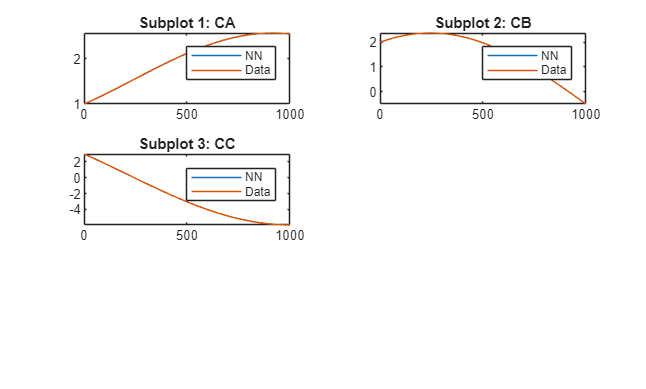

%%%%%%RESULT VALIDATION: Explicit Euler:
%(1) Calculate f'(x, t) using NN
% Assume t updates appropriately.
fNN = zeros(occurences-1, num_outputs);
fNN(1:3, :) = C(1:3, :); 
for i = 2:(occurences-2)
    %TODO: PHYSICS INFORMED:
    % fNN(i+1,1) = fNN(i,1) + dt(i) .* fNN(i,2);
    % fNN(i+1,2) = fNN(i,2) + dt(i) .* predict(trainedNet, [fNN(i, :) t(i)]);

    fNN(i+1,:) = fNN(i,:) + dt(i) .* predict(trainedNet, [fNN(i,:) t(i)]);
end %for

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(3,2);
ptitles = ['Subplot 1: CA'
    'Subplot 2: CB'
    'Subplot 3: CC'  
    'Subplot 4: CD'
    'Subplot 5: CE'
    'Subplot 6: CF'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

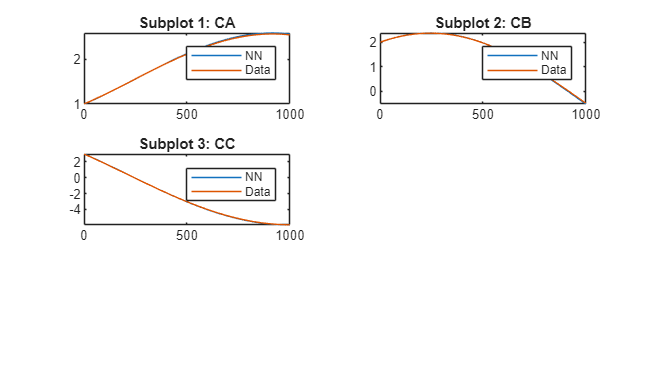

%%%%%%RESULT VALIDATION: FORWARD PASS:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1, :) = C(1, :);
numLayers = size(arraySize, 2);
for i = 1:(occurences-1)
    zk = [fNN(i, :)'; t(i)]; %update with time 
    zk = (zk - trainedNet.Layers(1).Mean') ./ trainedNet.Layers(1).StandardDeviation'; 
    for j = 1:numLayers
        zk = trainedNet.Layers(j*2).Weights * zk + trainedNet.Layers(j*2).Bias;
        zk = max(alphaParameter*zk, zk);
    end %for
    zk = trainedNet.Layers(2*(numLayers+1)).Weights * zk + trainedNet.Layers(2*(numLayers+1)).Bias; 
   
    fNN(i+1, :) = fNN(i, :) + dt(i) .* zk';
end %for 

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(3,2);
ptitles = ['Subplot 1: CA'
    'Subplot 2: CB'
    'Subplot 3: CC'  
    'Subplot 4: CD'
    'Subplot 5: CE'
    'Subplot 6: CF'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

**STORE DATA**

%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
numLayers = size(trainedNet.Layers, 1) / 2;

for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Weights ./ trainedNet.Layers(1).StandardDeviation;
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else 
        writematrix(trainedNet.Layers(j*2).Weights, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Bias - (trainedNet.Layers(j*2).Weights * (trainedNet.Layers(1).Mean ./ trainedNet.Layers(1).StandardDeviation)');
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else
        writematrix(trainedNet.Layers(j*2).Bias, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(C, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')